

%sets the order of the filter
filterOrder = 3

filterOrder = 3


%sets the corner Frequency
cornerFrequency = 300

cornerFrequency = 300


%sets the sample Frequency
sampleFrequency = 8000

sampleFrequency = 8000


%normalized corner
normalizedCorner = cornerFrequency/(sampleFrequency/2)

normalizedCorner = 0.0750


%gets the b and a coefficients
[b, a] = butter(filterOrder, normalizedCorner)

b =     0.0013    0.0039    0.0039    0.0013


a =     1.0000   -2.5298    2.1638   -0.6235


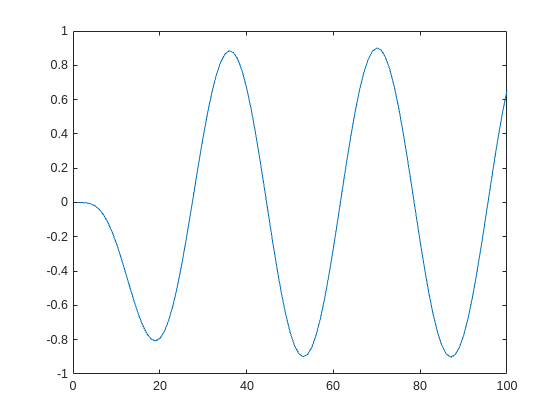


%creates the signal
signalLength = 400;

x_signal = zeros(signalLength);

for i = 1:signalLength
    x_signal(i) = cos((pi/17)*(i-1) + pi/2);
end


%calls the filter function on this signal
y_signal = filter(b, a, x_signal);

plot(y_signal(1:100))


y_signal = reshape(y_signal,1,[])

y_signal =     0.0000   -0.0002   -0.0018   -0.0069   -0.0182   -0.0386   -0.0702   -0.1141   -0.1706   -0.2385   -0.3158   -0.3994   -0.4853   -0.5693   -0.6467   -0.7131   -0.7642   -0.7964   -0.8066   -0.7930   -0.7545   -0.6911   -0.6040   -0.4955   -0.3686   -0.2273   -0.0763    0.0793    0.2342    0.3830    0.5203    0.6412    0.7414    0.8171    0.8656    0.8849    0.8742    0.8336    0.7646    0.6692    0.5507    0.4132    0.2612    0.0999   -0.0650   -0.2281   -0.3836   -0.5262   -0.6511   -0.7539


y_signal = y_signal.'

y_signal =     0.0000
   -0.0002
   -0.0018
   -0.0069
   -0.0182
   -0.0386
   -0.0702
   -0.1141
   -0.1706
   -0.2385


y_signal = y_signal(1:signalLength)

y_signal =     0.0000
   -0.0002
   -0.0018
   -0.0069
   -0.0182
   -0.0386
   -0.0702
   -0.1141
   -0.1706
   -0.2385



%writes the y_signal to a csv
csvwrite("matlab_y_signal.csv", y_signal)